# **Uncertainty of arrival-time picking**

## Introduction

Arrival time picking is never accurate and it's uncertainty depends on the signal-to-noise level and parameters of the signal.   

**Authors**: I. Abakumov, A. Roeser, S.A. Shapiro

**Publication date**: 10th of May 2019

**E-mail**: ivan.abakumov@fu-berlin.de

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Definition of basic values

Fs = 4000;              % sampling frequency
dt = 1/Fs;              % time step 
fc = 200;               % dominant frequency of the signal
T  = 1/fc;              % central period
Ta = 1;                 % length of a priori interval [0 Ta]
damp  = 400;            % attenuation factor (for signal modeling)
sigma = 0.2;            % variance of noise is equal sigma^2
tau = 0.45242;          % arrival time
t = 0:dt:1-dt;

## Definition of signals and noise

$\tau$ is an arrival time

Symmetric signal:


$$s\left(t\right)=\mathrm{cos}\left(2\pi \;f_{c\;} \left(t-\tau \;\right)\right)e^{-A|t-\tau |}$$


get_sym_signal  = @(t,tau,fc,damp)(   cos(2*pi*fc*(t-tau)).*exp(-damp*abs(t-tau))   );
get_sym_true_signal = @(t,t0,fc,damp)(   cos(2*pi*fc*(t-t0 )).*exp(-damp*abs(t-t0))       );

Non-symmetric signal:


$$s\left(t\right)=h\left(t\right)\cdot \;\mathrm{sin}\left(2\pi \;f_{c\;} \left(t-\tau \;\right)\right)e^{-A\left|t-\tau \right|}$$


get_nsm_signal  = @(t,tau,fc,damp)(   myheaviside(t-tau).*sin(2*pi*fc*(t-tau)).*exp(-damp*(t-tau))   );
get_nsm_true_signal = @(t,t0,fc,damp)(myheaviside(t-t0).*sin(2*pi*fc*(t-t0) ).*exp(-damp*(t-t0))    );

Noise:

get_noise = @(t,sigma)(   sigma*randn(size(t))   );

## Spectral variance of the signal, energy of the signal, noise spectral density

### 1. Spectral variance

There are two definitions of spectral variance of the signal (angular bandwidth of the pulse) $\beta$ 

in the frequency domain:


$$\beta^2 = \frac{\int_{-\infty}^{\infty} \omega^2  |S(\omega)|^2  d \omega}{ \int_{-\infty}^{\infty}   |S(\omega)|^2  d \omega},
$$


and in the time domain: 


$$ \beta^2 =  \frac{\int  |s'_t (t)|^2  d t} { \int   |s(t)|^2  d t},
$$


These definitions are identical.

get_beta = @(signal,dt)(   sqrt(sum((diff(signal,1)/dt).^2)/sum(signal.^2))   );

### 2. Definition of signal energy


$$W = \int_{-\infty}^{\infty} {\Big| s(t) \Big|}^2 dt$$


### 3. Definition of noise: 

Additive white Gaussian noise (AWGN) has a normal distribution $\mathcal{N}(\mu,\sigma^2)$, where

$\mu \;$- is a mean value (we assume $\mu =0$),

$\sigma^{2\;}$- is a variance of noise.

$N_{0\;} /2$ **double-sided** power spectral density of noise (NB!! In our fornulas $N_0 \equiv \frac{N_0 }{2}$)

Noise: **one-sided** vs **double-sided** power spectral density

$B$ is the bandwidth 

$F_s =\frac{1}{\mathrm{dt}}$ sampling frequency

$B=F_s/2$ for one-sided case (spectral density $N_0$)

$B = F_s$ double-sided case (spectral density $N_0/2$)


$$N_0/2 = \frac{\sigma^2}{F_s} = \sigma^2 dt$$


Note: when computing power spectral density:

- multiply the positive and negative frequencies by a factor of 2; 

- zero frequency (DC) and the Nyquist frequency do not occur twice.

### 4. Signal to noise ratio:


$$\mathrm{SNR}=\frac{W}{N_0 }$$



$${\mathrm{SNR}}_{\mathrm{dB}} =10\;{\mathrm{log}}_{10} \mathrm{SNR}$$


## Uncertainty bounds

### 1. Cramer-Rao bound (eq. 9, 11)


$$CRB = \frac{1}{\beta^{2}}
\frac{N_0}{W} \equiv
\frac{1}{\beta^{2}}
\frac{1}{SNR}$$


get_CRB = @(SNR,beta)(   1./beta.^2./SNR   );

### 2. Ziv Zakai Bound (eq. 17)

Original formula from:

Bell, K. L., Steinberg, Y., Ephraim, Y., & Van Trees, H. L. (1997). Extended Ziv-Zakai lower bound for vector parameter estimation. IEEE Transactions on Information Theory, 43(2), 624-637.

equation 108:


$$\textrm{ZZB}=\frac{T_a^2 }{6}\Phi \left(\sqrt{\frac{W}{2N_0 }\;}\right)+\frac{N_0 }{\beta^{2\;} W\;}\Gamma_{\frac{3}{2}} \left(\frac{W}{4N_0 \;}\right)-{\left(\frac{N_0 }{\beta^{2\;} W\;}\right)}^{\frac{3}{2}} \frac{32}{3T_{a\;} \sqrt{2\pi }}\Gamma_2 \left(\frac{W}{4N_0 \;}\right)$$


where


$$\Phi \;\left(z\right)=\int_z^{\infty \;} \frac{\;1}{\sqrt{\;2\pi \;}}e^{-\frac{v^2 \;}{2}} \textrm{dv}\;\;\;$$


In matlab exists function 


$$\textrm{ercf}\;\left(z\right)=\int_z^{\infty \;} \frac{\;2}{\sqrt{\;\pi \;}}e^{-t^2 } \textrm{dt}\;\;\;$$



$$2\Phi \;\left(\sqrt{2}x\right)=\textrm{erfc}\left(x\right)$$
       

Hence, in our code and manuscript:


$$ZZB = \frac{T_a^2}{12} \mathrm{erfc}\left(\sqrt{\frac{W}{4N_0}}\right)+
\frac{N_0}{\beta^2 W}
\Gamma_{\frac{3}{2}} \left(\frac{W}{4N_0}\right) -{\left(
\frac{N_0}{\beta^2 W}
\right)}^{\frac{3}{2}} \frac{32}{3T_{a} \sqrt{2\pi }}\Gamma_2 \left(\frac{\mathrm{W}}{4N_0}\right).$$


Also note that 

$\Gamma_a \left(x\right)=\textrm{gammainc}\left(x,a\right)$.

and


$$\mathrm{SNR}\equiv \;\frac{W}{N_0 }\;$$


get_ZZB = @(SNR,beta,Ta)(   Ta^2/12*erfc(sqrt(SNR/4)) ...
    + (beta.^(-2)./SNR)*gammainc(SNR/4,3/2) ...
    - (beta.^(-2)./SNR).^1.5.*(32/(3*Ta*sqrt(2*pi))).*gammainc(SNR/4,2)   );

### 3. Shapiro bound (eq. 18)


$$CRB = \frac{T_d^2}{4\pi^{2}}
\frac{1}{\mathrm{SNR}}$$
   

get_SB  = @(SNR, Td)(   (Td/(2*pi))^2./SNR   );

### 4. Seismic ZZ bound (eq. 20)


$$SZZB =  \frac{T_a^2}{12}\mathrm{erfc}\left(\sqrt{\frac{\mathrm{SNR} }{4}}\right)+
\frac{1}{\mathrm{SNR}}\frac{T_d^2}{4\pi^{2}}
\Gamma_{\frac{3}{2}} \left(\frac{\mathrm{SNR}}{4}\right) -{\left(
\frac{1}{\mathrm{SNR}}\frac{T_d^2}{4\pi^{2}}
\right)}^{\frac{3}{2}} \frac{32}{3T_{a} \sqrt{2\pi }}\Gamma_2 \left(\frac{\mathrm{SNR}}{4}\right).$$


get_SZZB = @(SNR,Td,Ta)(   Ta^2/12*erfc(sqrt(SNR/4)) ...
    + (Td^2/(4*pi^2)./SNR)*gammainc(SNR/4,3/2) ...
    - (Td^2/(4*pi^2)./SNR).^1.5.*(32/(3*Ta*sqrt(2*pi))).*gammainc(SNR/4,2)   );

## Example how to use bounds

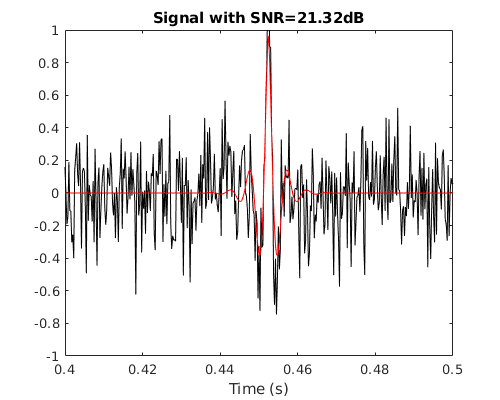

signal = get_sym_signal(t,tau,fc,damp);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;

beta = get_beta(signal,dt);
Td = 1/fc; 
W  = sum(signal.^2)*dt;
N0 = var(noise)*dt;
SNR = W/N0;
SNRdb = 10*log10(SNR);

figure(11)
fig = figure('Position', [1 1 500 400]);
plot(t, noisySignal,'k');
hold on 
plot(t, signal,'r');
axis([0.4 0.5 -1 1])
xlabel('Time (s)')
title(['Signal with SNR=' num2str(SNRdb,4) 'dB'])


CRB = get_CRB(SNR,beta);
ZZB = get_ZZB(SNR,beta,Ta);
SB  = get_SB(SNR,Td);
SZZB = get_SZZB(SNR,Td,Ta);

disp(['Cramer-Rao Bound is equal: ' num2str(CRB*1e6) ' ms^2']);

Cramer-Rao Bound is equal: 0.0043478 ms^2


disp(['Ziv-Zakai Bound is equal: ' num2str(ZZB*1e6) ' ms^2']);

Ziv-Zakai Bound is equal: 0.0043465 ms^2


disp(['Shapiro Bound is equal: ' num2str(SB*1e6) ' ms^2']);

Shapiro Bound is equal: 0.0046677 ms^2


disp(['Seismic Ziv-Zakai Bound is equal: ' num2str(SZZB*1e6) ' ms^2']);

Seismic Ziv-Zakai Bound is equal: 0.0046663 ms^2


## **Numerical estimation of arrival-time uncertainty**

ntest = 1000;
error = zeros(1,ntest);

t0 = 4/fc;
trueSignal = get_sym_true_signal(t,t0,fc,damp);
signal = get_sym_signal(t,tau,fc,damp);
    
for j=1:ntest
    noise  = get_noise(t,sigma);
    noisySignal = signal + noise;    
    [time,~] = mycorr(trueSignal, noisySignal, dt);
    error(j) = time - tau + t0;
end

disp(['Mean arrival-time error after ' num2str(ntest) ' experiments is equal ' num2str(mean(error*10^3)) 'ms']);

Mean arrival-time error after 1000 experiments is equal 0.0011746ms


disp(['Variance of arrival-time error after ' num2str(ntest) ' experiments is equal ' num2str(var(error*10^3)) 'ms^2']);

Variance of arrival-time error after 1000 experiments is equal 0.0042585ms^2


## **Detect optimum number of numerical tests to achieve stable values of variance**

required = 0;
if(required)
    NRT = 100;
    Tmean = zeros(1,NRT);
    Tvar  = zeros(1,NRT);
    Ntest = round(10.^(4*rand(1,NRT)));
    
    t0 = 4/fc;
    trueSignal = get_sym_true_signal(t,t0,fc,damp);
    sigma = 0.2;
    
    for i=1:length(Ntest)
        ntest = Ntest(i);
        error = zeros(1,ntest);
        for j=1:ntest
            tau = 0.4+0.1*rand(1);
            signal = get_sym_signal(t,tau,fc,damp);
            noise  = get_noise(t,sigma);
            noisySignal = signal + noise;
            [time,~] = mycorr(trueSignal, noisySignal, dt);
            error(j) = time - tau + t0;
        end
        Tmean(i) = mean(error);
        Tvar(i) = var(error);
    end   
    
    fig = figure(21);
    set(fig, 'Position', [100 100 1000 500])
    subplot(1,2,1)
    semilogx(Ntest, Tmean, '.k');
    hold on
    plot(linspace(1, 10000, 100), zeros(1,100), 'r--');
    ylabel('Mean value of \tau (s)')
    xlabel('Number of observations')
    axis('square')
    
    subplot(1,2,2)
    semilogx(Ntest, Tvar, '.k');
    ylabel('Variance of \tau (s^2)')
    xlabel('Number of observations')
    axis('square')
end

#### Conclusion

1000 - 10000 experiments is optimal to determine varicance numerically

## Behaviour of variance for different SNR

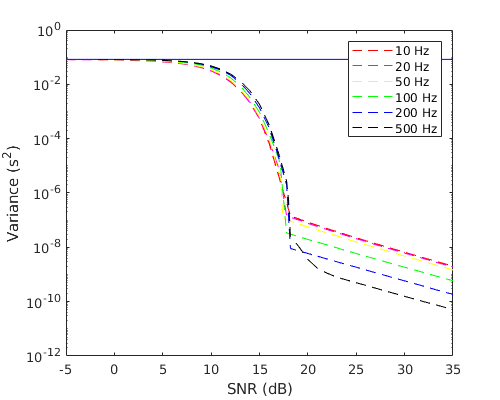

SNRdb = [-5:1:17 17.2:0.2:18.8 19:35];
SNR = 10.^(SNRdb/10);
FC = [10 20 40 100 200 400];

repeat_computations = 0;
if (repeat_computations)
    Variance.numeric = zeros(length(FC),length(SNRdb));
    Variance.sigma   = zeros(length(FC),length(SNRdb));
    Variance.FC = FC;
    Variance.SNR = SNR;
    Variance.SNRdb = SNRdb;
    
        
    ntest = 10000;   % use ntest = 100000 precise estimation of MSE in transition zone
    error = zeros(1,ntest);
    
    for k = 1:length(FC)
        fc = FC(k);
        t0 = 4/fc;
        trueSignal = get_sym_true_signal(t,t0,fc,damp);
        tau = 0.5; 
        signal = get_sym_signal(t,tau,fc,damp);
        W  = sum(signal.^2)*dt;
        for i = 1:length(SNRdb)
            sigma = sqrt(W/SNR(i)/dt);
            Variance.sigma(k,i) = sigma;
            for j=1:ntest
                tau = 0.4+0.1*rand(1);
                signal = get_sym_signal(t,tau,fc,damp);
                noise  = get_noise(t,sigma);
                noisySignal = signal + noise;
                [time,~] = mycorr(trueSignal, noisySignal, dt);
                error(j) = time - tau + t0;
            end
            Variance.numeric(k,i) = var(error);
        end
    end
else
    Variance = MLD([mlibfolder '/Examples/Arrival_time_uncertainty/Precomputed_MSE.mat']);

end

figure(31)
fig = figure('Position', [1 1 500 400]);
semilogy(SNRdb,Variance.numeric(1,:), 'r--')
hold on
semilogy(SNRdb,Variance.numeric(2,:), 'm--')
semilogy(SNRdb,Variance.numeric(3,:), 'y--')
semilogy(SNRdb,Variance.numeric(4,:), 'g--')
semilogy(SNRdb,Variance.numeric(5,:), 'b--')
semilogy(SNRdb,Variance.numeric(6,:), 'k--')
semilogy(SNRdb,ones(size(SNRdb))*(1/12), 'b')
legend('10 Hz', '20 Hz','50 Hz','100 Hz','200 Hz','500 Hz' );
xlabel('SNR (dB)')
ylabel('Variance (s^2)')
axis([-5 35 1e-12 1])

## **Compare numerical results with theoretical bounds**

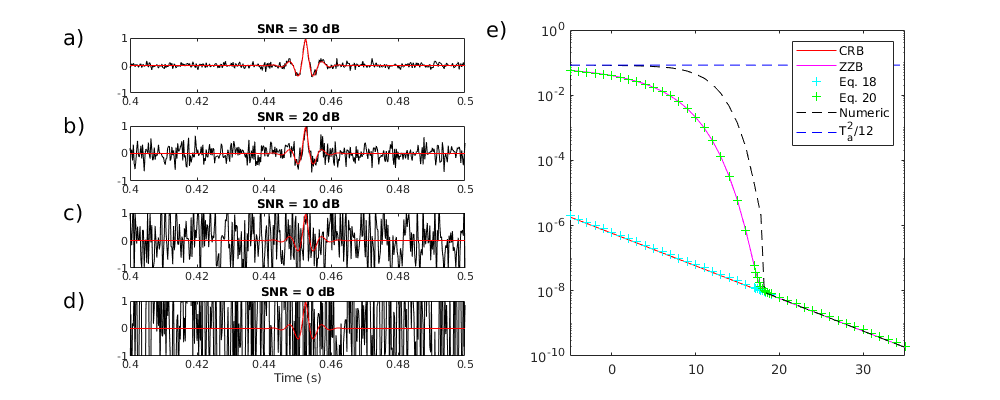

FC = Variance.FC;
SNR = Variance.SNR;
SNRdb = Variance.SNRdb;
Variance.CRB = zeros(length(FC),length(SNRdb));
Variance.ZZB = zeros(length(FC),length(SNRdb));
Variance.SB  = zeros(length(FC),length(SNRdb));
Variance.SZZB = zeros(length(FC),length(SNRdb));

for k = 1:length(FC)
    fc = FC(k);
    Td = 1/fc;
    tau = 0.5;
    signal = get_sym_signal(t,tau,fc,damp);
    beta = get_beta(signal,dt);
    for i = 1:length(SNRdb)
        snr = SNR(i);
        Variance.CRB(k,i) = get_CRB(snr,beta);
        Variance.ZZB(k,i) = get_ZZB(snr,beta,Ta);
        Variance.SB(k,i)  = get_SB(snr,Td);
        Variance.SZZB(k,i) = get_SZZB(snr,Td,Ta);
    end
end

figure(41)
fig = figure('Position', [1 1 1000 400]);
k = 5;      %    fc = 200 Hz
fc = Variance.FC(k);
tau = 0.45242;

subplot(4,2,1)
i = 44; 
sigma = Variance.sigma(k,i);
signal = get_sym_signal(t,tau,fc,damp);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'a)','FontSize',16)

subplot(4,2,3)
i = 34; 
sigma = Variance.sigma(k,i);
signal = get_sym_signal(t,tau,fc,damp);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'b)','FontSize',16)

subplot(4,2,5)
i = 16; 
sigma = Variance.sigma(k,i);
signal = get_sym_signal(t,tau,fc,damp);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'c)','FontSize',16)

subplot(4,2,7)
i = 6; 
sigma = Variance.sigma(k,i);
signal = get_sym_signal(t,tau,fc,damp);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
xlabel('Time (s)')
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'d)','FontSize',16)

subplot(4,2,[2 4 6 8])
semilogy(SNRdb,Variance.CRB(k,:), 'r')
hold on
semilogy(SNRdb,Variance.ZZB(k,:), 'm')
semilogy(SNRdb,Variance.SB(k,:), 'c+')
semilogy(SNRdb,Variance.SZZB(k,:), 'g+')
semilogy(SNRdb,Variance.numeric(k,:), 'k--')
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b')
legend('CRB', 'ZZB', 'Eq. 18', 'Eq. 20', 'Numeric', 'T_a^2/12');
text(-15,1.0,'e)','FontSize',16)
axis([-5 35 1e-10 1])

## Figures for EAGE poster (1)

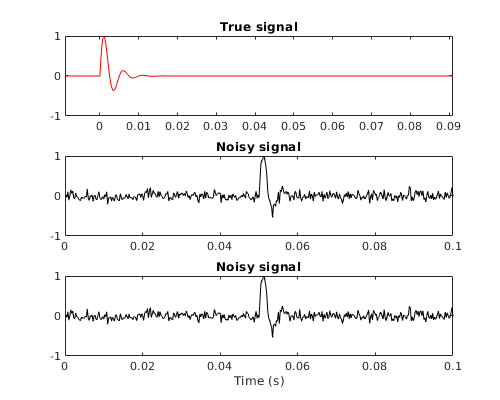

figure(31)
fig = figure('Position', [1 1 500 400]);

t0=0.05;
signal = get_nsm_true_signal(t,t0,fc,damp);
signal = signal/max(signal);

W  = sum(signal.^2)*dt;
snrdb = 30;
snr = 10.^(snrdb/10);
sigma = sqrt(W/snr/dt);

noise = get_noise(t,sigma);
noisySignal = signal + noise;

subplot(3,1,1);
plot(t-t0,signal,'r');
axis([-0.009 0.091 -1 1])
title('True signal')

subplot(3,1,2);
plot(t,noisySignal,'k');
%hold on
%plot(t,signal,'r');
axis([0 0.1 -1 1])
title('Noisy signal')

subplot(3,1,3);
plot(t,noisySignal,'k');
%hold on
%plot(t,signal,'r');
axis([0 0.1 -1 1])
title('Noisy signal')
xlabel('Time (s)')

## Figures for EAGE poster (2) 

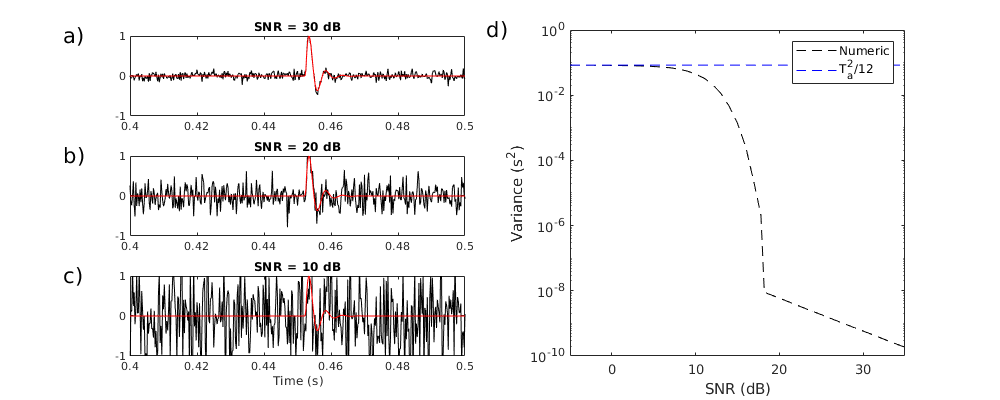

figure(81)
fig = figure('Position', [1 1 1000 400]);
k = 5;      %    fc = 200 Hz
fc = Variance.FC(k);
tau = 0.45242;

subplot(3,2,1)
i = 44; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'a)','FontSize',16)

subplot(3,2,3)
i = 34; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'b)','FontSize',16)

subplot(3,2,5)
i = 16; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.38,1,'c)','FontSize',16)
xlabel('Time (s)')

subplot(3,2,[2 4 6])
semilogy(SNRdb,Variance.numeric(k,:), 'k--')
hold on
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b')
legend('Numeric', 'T_a^2/12');
text(-15,1.0,'d)','FontSize',16)
axis([-5 35 1e-10 1])
xlabel('SNR (dB)')
ylabel('Variance (s^2)')

## Figures for EAGE poster (3)

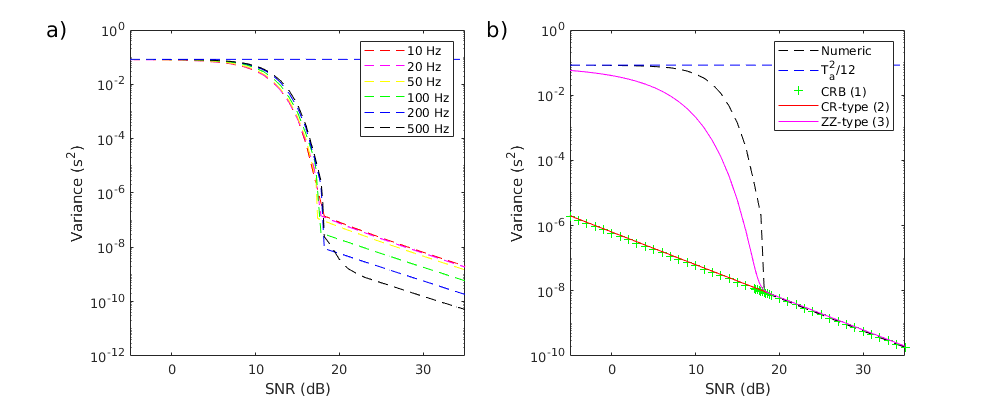


figure(8122)
fig = figure('Position', [1 1 1000 400]);
k = 5;      %    fc = 200 Hz
fc = Variance.FC(k);
tau = 0.45242;


subplot(1,2,1)
semilogy(SNRdb,Variance.numeric(1,:), 'r--')
hold on
semilogy(SNRdb,Variance.numeric(2,:), 'm--')
semilogy(SNRdb,Variance.numeric(3,:), 'y--')
semilogy(SNRdb,Variance.numeric(4,:), 'g--')
semilogy(SNRdb,Variance.numeric(5,:), 'b--')
semilogy(SNRdb,Variance.numeric(6,:), 'k--')
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b')
legend('10 Hz', '20 Hz','50 Hz','100 Hz','200 Hz','500 Hz' );
xlabel('SNR (dB)')
ylabel('Variance (s^2)')
text(-15,1.0,'a)','FontSize',16)
axis([-5 35 1e-12 1])


subplot(1,2,2)
semilogy(SNRdb,Variance.numeric(k,:), 'k--')
hold on
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b')
semilogy(SNRdb,Variance.CRB(k,:), 'g+')
semilogy(SNRdb,Variance.SB(k,:), 'r')
semilogy(SNRdb,Variance.SZZB(k,:), 'm')
legend('Numeric', 'T_a^2/12', 'CRB (1)', 'CR-type (2)', 'ZZ-type (3)');
text(-15,1.0,'b)','FontSize',16)
axis([-5 35 1e-10 1])
xlabel('SNR (dB)')
ylabel('Variance (s^2)')

## Figures for Paper (1)

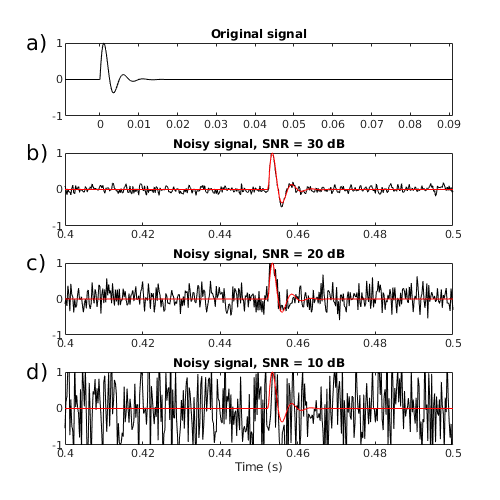

figure(61)
fig = figure('Position', [1 1 500 500]);

k = 5;      %    fc = 200 Hz
fc = Variance.FC(k);
tau = 0.45242;
t0=0.05;

signal = get_nsm_true_signal(t,t0,fc,damp);
signal = signal/max(signal);

W  = sum(signal.^2)*dt;
snrdb = 30;
snr = 10.^(snrdb/10);
sigma = sqrt(W/snr/dt);

noise = get_noise(t,sigma);
noisySignal = signal + noise;

subplot(4,1,1);
plot(t-t0,signal,'black');
axis([-0.009 0.091 -1 1])
title('Original signal')
text(-0.019,1,'a)','FontSize',16)

subplot(4,1,2)
i = 44; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['Noisy signal, SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.39,1,'b)','FontSize',16)

subplot(4,1,3)
i = 34; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['Noisy signal, SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.39,1,'c)','FontSize',16)

subplot(4,1,4)
i = 16; 
sigma = Variance.sigma(k,i);
signal = get_nsm_signal(t,tau,fc,damp);
signal = signal/max(signal);
noise  = get_noise(t,sigma);
noisySignal = signal + noise;
plot(t,noisySignal,'black');
hold on
plot(t,signal,'red');
title(['Noisy signal, SNR = ' num2str(Variance.SNRdb(i)) ' dB'])
axis([0.4 0.5 -1 1])
text(0.39,1,'d)','FontSize',16)
xlabel('Time (s)')

## Figures for Paper (2)

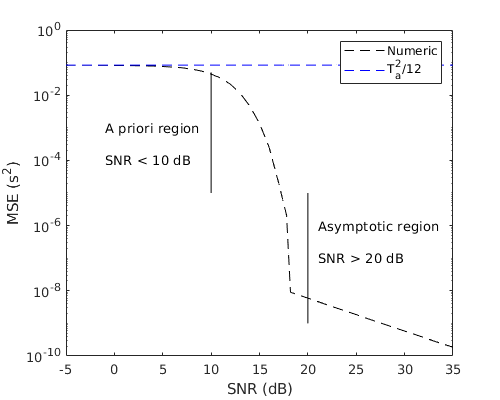

figure(353843)
fig = figure('Position', [1 1 500 400]);
h1 = semilogy(SNRdb,Variance.numeric(k,:), 'k--');
hold on
h2 = semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b');
line([10 10], [1e-5 0.5e-1],'Color','black','LineStyle','-')
text(-1,1e-3,'A priori region','FontSize',10)
text(-1,1e-4,'SNR < 10 dB','FontSize',10)
line([20 20], [1e-5 1e-9],'Color','black','LineStyle','-')
text(21,1e-6,'Asymptotic region','FontSize',10)
text(21,1e-7,'SNR > 20 dB','FontSize',10)
legend([h1 h2], 'Numeric', 'T_a^2/12');
axis([-5 35 1e-10 1])
xlabel('SNR (dB)')
ylabel('MSE (s^2)')

## Figures for Paper (3)

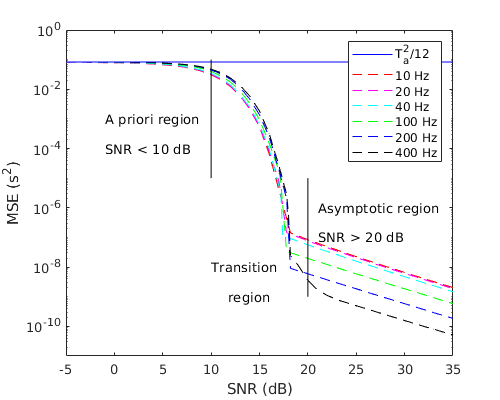

figure(353843)
fig = figure('Position', [1 1 500 400]);
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '-b');
hold on
semilogy(SNRdb,Variance.numeric(1,:), 'r--')
semilogy(SNRdb,Variance.numeric(2,:), 'm--')
semilogy(SNRdb,Variance.numeric(3,:), 'c--')
semilogy(SNRdb,Variance.numeric(4,:), 'g--')
semilogy(SNRdb,Variance.numeric(5,:), 'b--')
semilogy(SNRdb,Variance.numeric(6,:), 'k--')
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '--b')

line([10 10], [1e-5 1e-1],'Color','black','LineStyle','-')
text(-1,1e-3,'A priori region','FontSize',10)
text(-1,1e-4,'SNR < 10 dB','FontSize',10)
line([20 20], [1e-5 1e-9],'Color','black','LineStyle','-')
text(21,1e-6,'Asymptotic region','FontSize',10)
text(21,1e-7,'SNR > 20 dB','FontSize',10)
text(10,1e-8,'Transition','FontSize',10)
text(10,1e-9,'    region','FontSize',10)

legend('T_a^2/12', '10 Hz', '20 Hz','40 Hz','100 Hz','200 Hz','400 Hz' );
axis([-5 35 1e-11 1])
xlabel('SNR (dB)')
ylabel('MSE (s^2)')

## Figures for Paper (4)

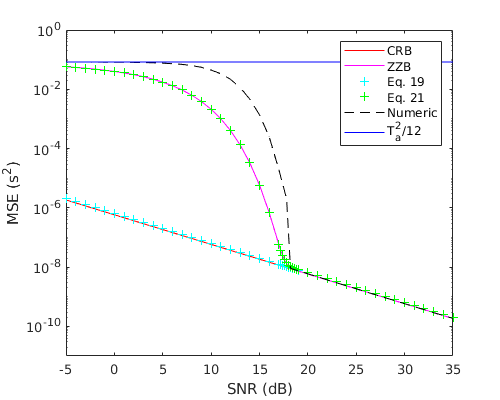

figure(353823)
fig = figure('Position', [1 1 500 400]);
semilogy(SNRdb,Variance.CRB(k,:), 'r')
hold on
semilogy(SNRdb,Variance.ZZB(k,:), 'm')
semilogy(SNRdb,Variance.SB(k,:), 'c+')
semilogy(SNRdb,Variance.SZZB(k,:), 'g+')
semilogy(SNRdb,Variance.numeric(k,:), 'k--')
semilogy(SNRdb,ones(size(SNRdb))*(1/12), '-b');
legend('CRB', 'ZZB', 'Eq. 19', 'Eq. 21', 'Numeric', 'T_a^2/12');
text(-15,1.0,'e)','FontSize',16)
axis([-5 35 1e-10 1])
axis([-5 35 1e-11 1])
xlabel('SNR (dB)')
ylabel('MSE (s^2)')